**2.1 Reading the image**

clear;
Intensity = 5;
my_image = Tiff('cornell_box.tiff','r');
imgData = read(my_image);
% imshow(min(imgData * Intensity, 1.0));
% title('Reading Image');

%Saving the image
% imwrite(min(imgData * Intensity, 1.0), '02_data.png');


2.1 Reading the image information

info = imfinfo('cornell_box.tiff');
bitsPerSample = info.BitsPerSample;
w = info.Width;
h = info.Height;

fprintf('Bits per sample: %s\n', num2str(bitsPerSample));

Bits per sample: 16


fprintf('Width: %s\n', num2str(w));

Width: 4770


fprintf('Height: %s\n', num2str(h));

Height: 3178


img_d = double(imgData);
%imshow(img_d);
%title('Doble Image');

%Saving the image
% imwrite(min(img_d * Intensity, 1.0), '02_double.png');

2.2 Linearization

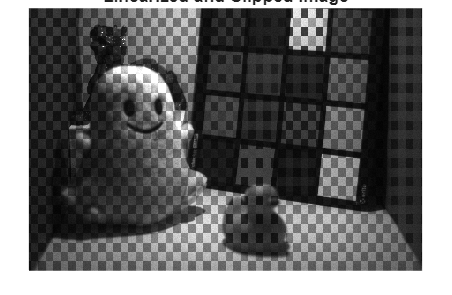

dark_noise = 1023;  % Dark noise threshold
saturation = 15600; % Saturation threshold

% Assuming 'img_d' is your input image (raw Bayer-filtered or any other)
I_linear = (img_d - dark_noise) / (saturation - dark_noise);  % Linearize the image

% Manually clip values outside the [0, 1] range
I_linear_clipped = max(min(I_linear, 1), 0);  % Clip values between 0 and 1

% Display the resulting image
imshow(min(I_linear_clipped * Intensity, 1.0));
title('Linearized and Clipped Image');


% Saving the image
% imwrite(min(I_linear_clipped * Intensity, 1.0), '02_linearized.png');

clear imgData img_d


**3 Demosaicing**

i) nearest neighbor 

corner_2x2 = I_linear_clipped(1:2,1:2);
disp('img_d_lin: ')

img_d_lin: 


disp(corner_2x2)

    0.0130    0.0327
    0.0348    0.0201




img_raw = imread('cornell_box.CR2');
corner_2x2_raw = img_raw(1:2, 1:2,:);
disp('img_raw: ')

img_raw: 


disp(corner_2x2_raw)


(:,:,1) =

   75   75
   76   77


(:,:,2) =

   91   91
   92   93


(:,:,3) =

   62   62
   65   66



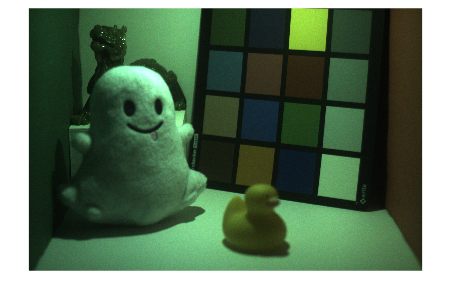


% Separate the color channels based on the Bayer pattern
% RGGB pattern

% Extract the Blue, Green, and Red channels for RGGB Bayer pattern

img_linear = I_linear_clipped;
[height, width] = size(img_linear);  % Get the dimensions of the image

% Separate the color channels based on the RGGB Bayer pattern
red_channel = zeros(height,width);
red_channel(1:2:end, 1:2:end) = img_linear(1:2:end, 1:2:end);  % Red: odd rows, odd columns
green_channel = zeros(height,width);
green_channel(1:2:end, 2:2:end) = img_linear(1:2:end, 2:2:end); % Green: even rows, odd columns
green_channel(2:2:end, 1:2:end) = img_linear(2:2:end, 1:2:end); % Green: odd rows, even columns
blue_channel = zeros(height,width);
blue_channel(2:2:end, 2:2:end) = img_linear(2:2:end, 2:2:end);   % Blue: even rows, even columns


%% 1. Fill Red Channel (Known at 1,1)
% Copy the value at (1,1) to the rest of the 2x2 block
red_full = red_channel;
red_full(1:2:end, 2:2:end) = red_full(1:2:end, 1:2:end); % Copy Right
red_full(2:2:end, 1:2:end) = red_full(1:2:end, 1:2:end); % Copy Down
red_full(2:2:end, 2:2:end) = red_full(1:2:end, 1:2:end); % Copy Diagonal

%% 2. Fill Blue Channel (Known at 2,2)
% Copy the value at (2,2) to the rest of the 2x2 block
blue_full = blue_channel;
blue_full(1:2:end, 1:2:end) = blue_full(2:2:end, 2:2:end); % Copy Diagonal Up
blue_full(1:2:end, 2:2:end) = blue_full(2:2:end, 2:2:end); % Copy Up
blue_full(2:2:end, 1:2:end) = blue_full(2:2:end, 2:2:end); % Copy Left

%% 3. Fill Green Channel (Known at 1,2 and 2,1)
% Since we have two greens, we just fill the missing spots with the nearest one
green_full = green_channel;
green_full(1:2:end, 1:2:end) = green_full(1:2:end, 2:2:end); % Top-left gets Top-right
green_full(2:2:end, 2:2:end) = green_full(2:2:end, 1:2:end); % Bottom-right gets Bottom-left



img_rgbNN = cat(3,red_full,green_full,blue_full);
% Display the RGB image
imshow(min(img_rgbNN * Intensity, 1.0));

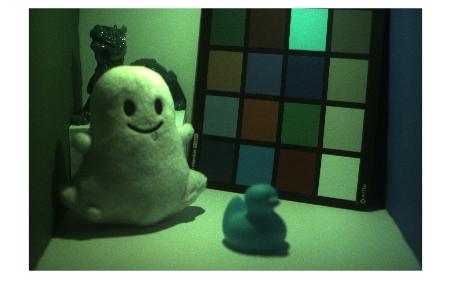

% title('Demosaiced RGB Image / first way');
% imwrite(min(img_rgbNN * Intensity, 1.0), '03_NN_interpolation.png');

img_wrong_mosaic = cat(3, blue_full,green_full,red_full);
imshow(min(img_wrong_mosaic * Intensity, 1.0));

% title('Demosaiced RGB Image: BGGR (wrong)');
% imwrite(min(img_wrong_mosaic * Intensity, 1.0), '03_NN_interpolation_BGGR_wrong.png');


ii) bilinear interpolation 

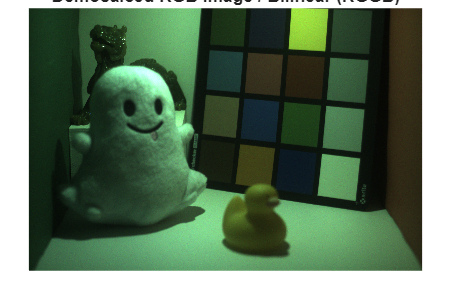

red_full_bil   = red_channel;
green_full_bil = green_channel;
blue_full_bil  = blue_channel;


%Red
cols = 2:2:width-1;
rows = 2:2:height-1;
red_full_bil(1:2:end, cols) = ...
    ( red_channel(1:2:end, cols-1) + red_channel(1:2:end, cols+1) ) / 2;
red_full_bil(rows, 1:2:end) = ...
    ( red_channel(rows-1, 1:2:end) + red_channel(rows+1, 1:2:end) ) / 2;
red_full_bil(rows, cols) = ...
    ( red_channel(rows-1, cols-1) + red_channel(rows-1, cols+1) + ...
      red_channel(rows+1, cols-1) + red_channel(rows+1, cols+1) ) / 4;


red_full_bil(end,:) = red_full_bil(end-1,:);
red_full_bil(:,end) = red_full_bil(:,end-1);

%Blue
cols = 3:2:width-1;
rows = 3:2:height-1;
blue_full_bil(2:2:end, cols) = ...
    ( blue_channel(2:2:end, cols-1) + blue_channel(2:2:end, cols+1) ) / 2;
blue_full_bil(rows, 2:2:end) = ...
    ( blue_channel(rows-1, 2:2:end) + blue_channel(rows+1, 2:2:end) ) / 2;
blue_full_bil(rows, cols) = ...
    ( blue_channel(rows-1, cols-1) + blue_channel(rows-1, cols+1) + ...
      blue_channel(rows+1, cols-1) + blue_channel(rows+1, cols+1) ) / 4;

blue_full_bil(1,:) = blue_full_bil(2,:);
blue_full_bil(:,1) = blue_full_bil(:,2);

%Green
rows = 3:2:height-1;  
cols = 3:2:width-1;   
green_full_bil(rows-2, cols-2) = ...
    ( green_channel(rows-1, cols) + ...   
      green_channel(rows, cols-1) + ...   
      green_channel(rows-2, cols-1) + ... 
      green_channel(rows-1, cols-2) ) / 4;

green_full_bil(rows-1, cols-1) = ...
    ( green_channel(rows-1, cols) + ...   
      green_channel(rows, cols-1) + ...   
      green_channel(rows-2, cols-1) + ... 
      green_channel(rows-1, cols-2) ) / 4;
 

img_rgbBL = cat(3, red_full_bil, green_full_bil, blue_full_bil);

imshow(min(img_rgbBL * Intensity, 1.0));
title('Demosaiced RGB Image / Bilinear (RGGB)');

% imwrite(min(img_rgbBL * Intensity, 1.0), '03_Bilinear_RGGB.png');


clear I_linear I_linear_clipped img_linear red_channel green_channel blue_channel rows cols
clear img_rgbNN red_full green_full blue_full red_full_bil blue_full_bil green_full_bil img_raw

clear img_wrong_mosaic

**4 White balancing**

i) White world balancing

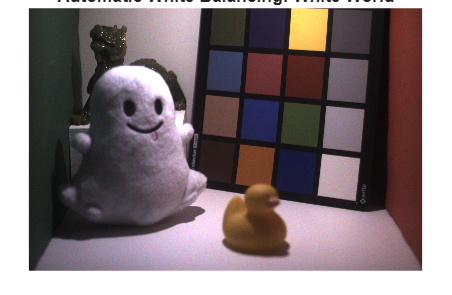

% Find the maximum value in each channel
R_max = max(img_rgbBL(:,:,1), [], 'all');
G_max = max(img_rgbBL(:,:,2), [], 'all');
B_max = max(img_rgbBL(:,:,3), [], 'all');

% Compute the scale factors based on the assignment formula
SR_w = G_max / R_max;
SB_w = G_max / B_max;

% Create the corrected image
rgb_white_world = img_rgbBL;
rgb_white_world(:,:,1) = img_rgbBL(:,:,1) * SR_w;
rgb_white_world(:,:,2) = img_rgbBL(:,:,2);
rgb_white_world(:,:,3) = img_rgbBL(:,:,3) * SB_w;

% Display the result
imshow(min(rgb_white_world * Intensity, 1.0));
title('Automatic White Balancing: White World');

% imwrite(min(rgb_white_world * Intensity, 1.0), '04_white_world.png');


ii)   Gray world balancing

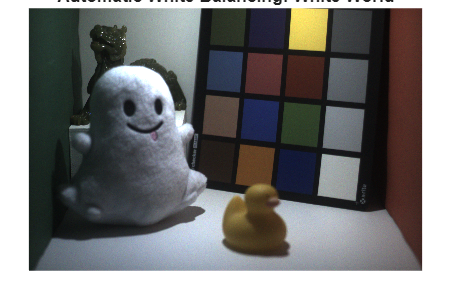

% Calculate the average (mean) value for each channel
R_avg = mean(img_rgbBL(:,:,1), 'all');
G_avg = mean(img_rgbBL(:,:,2), 'all');
B_avg = mean(img_rgbBL(:,:,3), 'all');

SR_g = G_avg / R_avg;
SB_g = G_avg / B_avg;

% Create the corrected image
rgb_gray_world = img_rgbBL;
rgb_gray_world(:,:,1) = img_rgbBL(:,:,1) * SR_g;
rgb_gray_world(:,:,2) = img_rgbBL(:,:,2);
rgb_gray_world(:,:,3) = img_rgbBL(:,:,3) * SB_g;

% Display the result
imshow(min(rgb_gray_world  * Intensity, 1.0));
title('Automatic White Balancing: White World');

% imwrite(min(rgb_gray_world * Intensity, 1.0), '04_gray_world.png');

iii)  Manual white balancing

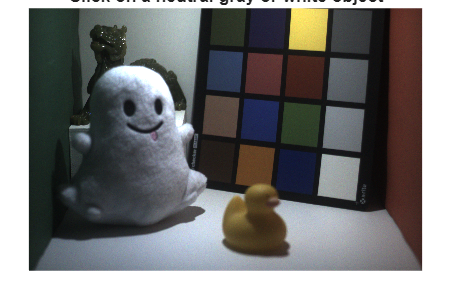

% Display the image so we can pick a point
% imshow(img_rgbBL * Intensity); % Scale for visibility if raw is dark
title('Click on a neutral gray or white object');

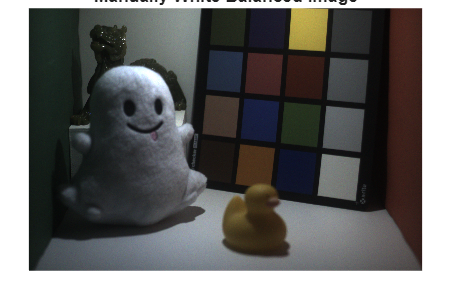


% Using ginput to get the coordinates of our choice
% [x, y] = ginput(1); 
% x = round(x) 
% y = round(y)
x = 3730;
y = 2060;

% Extracting the R, G, B values at that point
R_ref = img_rgbBL(y, x, 1);
G_ref = img_rgbBL(y, x, 2);
B_ref = img_rgbBL(y, x, 3);

% Compute the average intensity of the reference point
avg_ref = (R_ref + G_ref + B_ref) / 3;

% Compute the scale factors
SR = avg_ref / R_ref;
SG = avg_ref / G_ref;
SB = avg_ref / B_ref;

% Applying the scale factors to all pixels
rgb_wb = zeros(size(img_rgbBL));
rgb_wb(:,:,1) = img_rgbBL(:,:,1) * SR; 
rgb_wb(:,:,2) = img_rgbBL(:,:,2) * SG; 
rgb_wb(:,:,3) = img_rgbBL(:,:,3) * SB; 

% Display
imshow(min(rgb_wb * Intensity, 1.0)); 
title('Manually White Balanced Image');

% imwrite(min(rgb_wb * Intensity, 1.0), '04_white_manual.png');

clear img_rgbBL rgb_white_world rgb_gray_world

**5 Denoising**

i) mean filtering

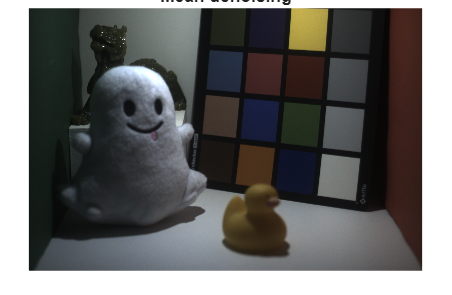

kernel_size = 3;
h = ones(kernel_size, kernel_size) / (kernel_size^2);

img_mean = zeros(size(rgb_wb));

for c = 1:3
    img_mean(:,:,c) = conv2(rgb_wb(:,:,c), h, 'same');
end

imshow(min(img_mean * Intensity, 1.0));
title('Mean denoising');

% imwrite(min(img_mean * Intensity, 1.0), '05_mean_denoising.png');


ii) median filtering

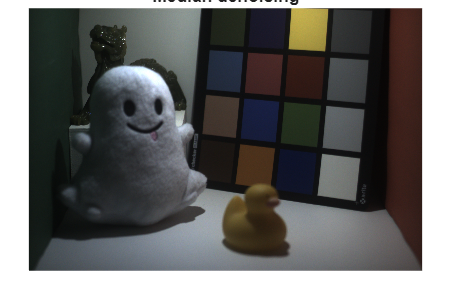

img_median = zeros(size(rgb_wb));
half = floor(kernel_size/2);

for c = 1:3
    for i = 1+half : height-half
        for j = 1+half : width-half
            window = rgb_wb(i-half:i+half, j-half:j+half, c);
            img_median(i,j,c) = median(window(:));
        end
    end
end

imshow(min(img_median * Intensity, 1.0));
title('Median denoising');

% imwrite(min(img_median * Intensity, 1.0), '05_median_denoising.png');

iii) Gaussian filtering.

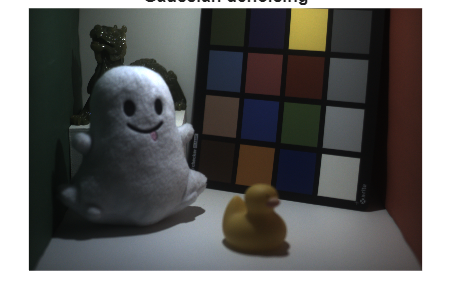

sigma = 1.0;

% Kernel size: 6*sigma + 1 % To mention this or changing it to 3x3
ksize = 2*ceil(3*sigma) + 1;
half  = floor(ksize/2);

[x, y] = meshgrid(-half:half, -half:half);
G = exp(-(x.^2 + y.^2) / (2*sigma^2)) / (2*pi*sigma^2);

img_gauss = zeros(size(rgb_wb));
for c = 1:3
    img_gauss(:,:,c) = conv2(rgb_wb(:,:,c), G, 'same');
end

imshow(min(img_gauss * Intensity, 1.0));
title('Gaussian denoising');

% imwrite(min(img_gauss * Intensity, 1.0), '05_gaussian_denoising.png');


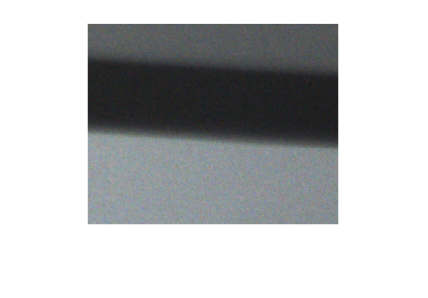

crop_rgb_wb = rgb_wb(500:700, 3750:4000, :);
crop_mean = img_mean(500:700, 3750:4000, :);
crop_median = img_median(500:700, 3750:4000, :);
crop_gauss = img_gauss(500:700, 3750:4000, :);
imshow(min(crop_rgb_wb * Intensity * 2, 1.0));

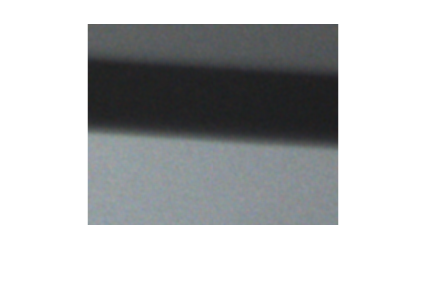

imshow(min(crop_mean * Intensity * 2, 1.0));

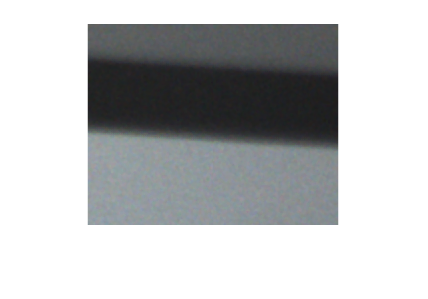

imshow(min(crop_median * Intensity * 2, 1.0));

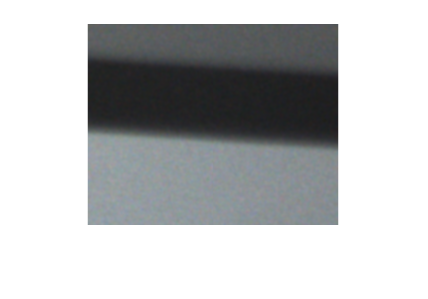

imshow(min(crop_gauss * Intensity * 2, 1.0));

% imwrite(min(crop_rgb_wb * Intensity * 2, 1.0), '05_crop_before_denoising.png');
% imwrite(min(crop_mean * Intensity * 2, 1.0), '05_crop_mean_denoising.png');
% imwrite(min(crop_median * Intensity * 2, 1.0), '05_crop_median_denoising.png');
% imwrite(min(crop_gauss * Intensity * 2, 1.0), '05_crop_gaussian_denoising.png');

clear rgb_wb img_mean img_median crop_rgb_wb crop_mean crop_median crop_gauss

**6 Color balance**

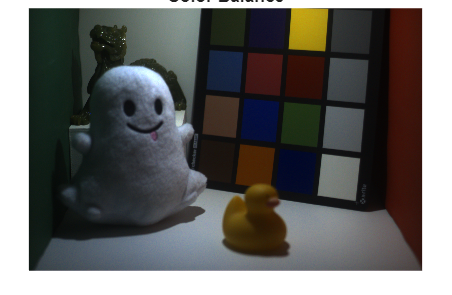

img_hsv = rgb2hsv(img_gauss);

boost_factor = 1.5; 
img_hsv(:,:,2) = img_hsv(:,:,2) * boost_factor;
img_hsv(:,:,2) = min(img_hsv(:,:,2), 1); % clamp to 1

img_cb = hsv2rgb(img_hsv);

imshow(min(img_cb * Intensity, 1.0));
title('Color Balance');

% imwrite(min(img_cb * Intensity, 1.0), '06_color_balance.png');

clear img_hsv

**7 Tone reproduction**

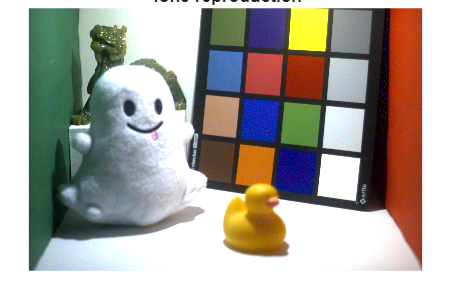

gamma = 1.8;      
% gamma = 2.4;      
alpha = 0;      

img_adjusted = img_cb * 2^alpha;

img_tone = zeros(size(img_adjusted));

for c = 1:3
    C = img_adjusted(:,:,c);

    mask = C <= 0.0031308;
    % C <= 0.0031308 case
    C_nonlin = zeros(size(C));
    C_nonlin(mask) = 12.92 * C(mask);

    % C > 0.0031308 case
    C_nonlin(~mask) = (1 + 0.055) * C(~mask).^(1/gamma) - 0.055;

    img_tone(:,:,c) = C_nonlin;
end

img_tone = min(max(img_tone, 0), 1); % clamp to 1

imshow(min(img_tone * Intensity, 1.0));
title('Tone reproduction');

imwrite(min(img_tone * Intensity, 1.0), '07_final_tone.png');

clear C C_nonlin mask

**8 Compression**

imwrite(min(img_tone * (Intensity-1), 1.0), '08_final_tone.png');
imwrite(min(img_tone * (Intensity-1), 1.0), '08_final_tone.jpg', 'Quality', 95);

%info
info_png = dir('08_final_tone.png');
info_jpg = dir('08_final_tone.jpg');

size_png = info_png.bytes;
size_jpg = info_jpg.bytes;

compression_ratio = size_png / size_jpg;

fprintf('PNG size: %d bytes\n', size_png);

PNG size: 17040272 bytes


fprintf('JPEG size: %d bytes\n', size_jpg);

JPEG size: 3224807 bytes


fprintf('Compression ratio (PNG/JPEG): %.2f\n', compression_ratio);

Compression ratio (PNG/JPEG): 5.28
